Examine a range of alphas for simulations where the enzyme decay rate is changed

%Generate/load the data
if ~exist('remcfg','var')
    load remoteconfig;
end

%reduce initial cellulose to reflect incomplete conversion
args.p8.v.initcellulose = args.default.v.initcellulose * 0.27;

args.p8.variableInitEnzyme = true;
args.p8.enzInMaint = false;
args.p8.v.addEnzymeToMaint = args.p8.enzInMaint;
v_default.addEnzymeToMaint = args.p8.enzInMaint;

args.p8.v.maxcycles = 1500;

args.p8.v.alpha = 0.0062;
args.p8.v.km_cel = 0.0909;
args.p8.v.kcat_cel = 45.2824;

args.p8.alphas = args.p8.v.alpha * 10.^(-2:.125:2);
args.p8.decayscales = 10.^(-2:.5:2);

args.p8.v_default = args.p8;
if runPart8
    layouts8 = part8_generation_remote(args.p8);
    [layouts8,remcfg] = runCometsRemotely(layouts8,remcfg);
else
    if ~exist('dat8','var')
        load([datadir '\dat8.mat']);
    end
end

if ~exist('dat8','var')
    dat8 = part8_parseRemoteResults(layouts8,remcfg.batchnum);
    layouts8 = dat8.layout;
    [nrows,~] = size(dat8);
    dat8.layout = cell(nrows,1);
    dat8.enzymeInMaint = repmat(args.p8.v.addEnzymeToMaint,nrows,1);
    dat8.variableInitEnzyme = repmat(args.p8.variableInitEnzyme,nrows,1);
end

Loading Media File ./log_1/media.m
Loading Media File ./log_2/media.m
Loading Media File ./log_3/media.m
Loading Media File ./log_4/media.m
Loading Media File ./log_5/media.m
Loading Media File ./log_6/media.m
Loading Media File ./log_7/media.m
Loading Media File ./log_8/media.m
Loading Media File ./log_9/media.m
Loading Media File ./log_10/media.m
Loading Media File ./log_11/media.m
Loading Media File ./log_12/media.m
Loading Media File ./log_13/media.m
Loading Media File ./log_14/media.m
Loading Media File ./log_15/media.m
Loading Media File ./log_16/media.m
Loading Media File ./log_17/media.m
Loading Media File ./log_18/media.m
Loading Media File ./log_19/media.m
Loading Media File ./log_20/media.m
Loading Media File ./log_21/media.m
Loading Media File ./log_22/media.m
Loading Media File ./log_23/media.m
Loading Media File ./log_24/media.m
Loading Media File ./log_25/media.m
Loading Media File ./log_26/media.m
Loading Media File ./log_27/media.m
Loading Media File ./log_28/media.m
L

%filter out rows which didn't finish
[nrows,~] = size(dat8);
if ~exist('dat8_allrows','var') %first, grab a backup
    dat8.layout = zeros(nrows,1);
    dat8_allrows = dat8;
else
    dat8.layout = zeros(nrows,1);
    dat8_allrows = vertcat(dat8_allrows,dat8);
    [~,ia,ic] = unique(dat8_allrows(:,{'alpha' 'decayscale'}),'rows');
    dat8_allrows = dat8_allrows(ia,:);
end

meandelta = zeros(nrows,1);
for i = 1:nrows
    meandelta(i) = mean(dat8.biomass_delta{i});
end
dat8 = dat8(meandelta ~= 0,:);
[nrows,~] = size(dat8);
finaldelta = zeros(nrows,1);
for i = 1:nrows
    delta = dat8.biomass_delta{i};
    finaldelta(i) = delta(end)/dat8.biomass_max(i);
    
end
dat8 = dat8(finaldelta < .0001,:);

%transform/collect data
decayscales = unique(dat8.decayscale);
logdecay = log10(decayscales);
alphas = unique(dat8.alpha);
dat8.log10alpha = log10(dat8.alpha);
logalphas = unique(dat8.log10alpha);

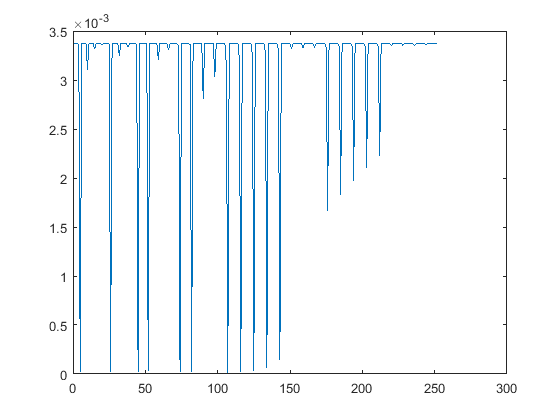

%check if everything finished running
cel_start = cellfun(@(x) x(1),dat8.cellulose_amt);
cel_final = cellfun(@(x) x(end),dat8.cellulose_amt);
plot(cel_start - cel_final);

%They did not...

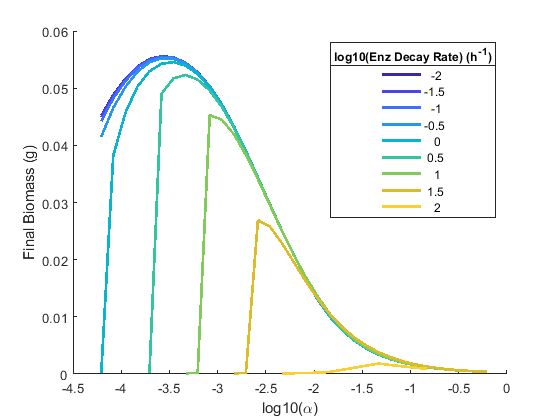

%plot the yield over alpha, decayrate in series
colors = parula(length(decayscales)+1);
figure();
hold on;
for i = 1:length(decayscales)
    scale = decayscales(i);
    subdat = dat8(dat8.decayscale == scale,:);
    subdat = sortrows(subdat,'alpha');
    plot(subdat.log10alpha,subdat.biomass_max,'color',colors(i,:),'LineWidth',2);
end
hold off;
leg = legend(num2str(log10(decayscales)),'location','northeast');
xlabel('log10(\alpha)');
ylabel('Final Biomass (g)');
title(leg,'log10(Enz Decay Rate) (h^-^1)');